clear;clc;

% load experimental data
data_h = xlsread('data_to_fit.xlsx', 3, 'B1:E3');
data_m = xlsread('data_to_fit.xlsx', 3, 'B5:E7');
data_mono = xlsread('data_to_fit.xlsx', 3, 'B9:E11');
data_neu = xlsread('data_to_fit.xlsx', 3, 'B13:E15');
data_nk = xlsread('data_to_fit.xlsx', 3, 'B17:E19');
data_v = xlsread('data_to_fit.xlsx', 3, 'B21:I23');
data_t = xlsread('data_to_fit.xlsx', 3, 'B25:G27');
data_te = xlsread('data_to_fit.xlsx', 3, 'B29:G31');
data_il1b = xlsread('data_to_fit.xlsx', 3, 'B33:E35');
data_ccl2 = xlsread('data_to_fit.xlsx', 3, 'B37:E39');

data_inf_score = xlsread('data_to_fit.xlsx', 3, 'B41:C43');
    
% data_v(2:3, :) = 10 .^ data_v(2:3, :);

% load immunity and clock-immunity parameters
par_IAV = importdata('par_base_IAV_clock_values.txt');
par_IAV = par_IAV.data;

% translate parFit to par in the odes
% log_par_ind = [1:38 42:53];
% for i = log_par_ind
%     par_base(i) = 10 .^ par_base(i);
% end

% load clock parameters
par_clock = load('par_clock.csv');

% load inflammation parameters
par_infla = importdata('par_infla.txt');
par_infla = par_infla.data;

y0 = zeros(27, 1);
y0_IAV = importdata('init_base.txt');
y0_IAV = y0_IAV.data;
for i = 13:26
    y0(i) = y0_IAV(i - 12);
end

tmax = 2000;
tspan = 0:1:tmax;

% par_IAV(64) = 0.02;
% par_IAV(65) = 10000;
t_IAV_11 = 511;
[~, y1] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_11, par_infla);
infla1 = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla1(i) = inflammation(y1(i, 17), y1(i, 18), y1(i, 19), par_infla);
end

% clock ko
[~, y1_ko] = ode15s(@ODE_Clock_KO_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_11, par_infla);
infla1_ko = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla1_ko(i) = inflammation(y1_ko(i, 17), y1_ko(i, 18), y1_ko(i, 19), par_infla);
end

% par_IAV(70) = 0.02;
% par_IAV(71) = 10000;
% t_IAV_5 = 505;
% [~, y2] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_5, par_infla);
% infla2 = zeros(tmax+1, 1);
% for i = 1:(tmax+1)
%     infla2(i) = inflammation(y2(i, 17), y2(i, 18), y2(i, 19), par_infla);
% end

% par_IAV(70) = 10000;
% par_IAV(71) = 0.02;
% par_clock(8) = 0.6;
t_IAV_23 = 499;
[~, y3] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_23, par_infla);
infla3 = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla3(i) = inflammation(y3(i, 17), y3(i, 18), y3(i, 19), par_infla);
end

% clock ko
[~, y3_ko] = ode15s(@ODE_Clock_KO_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_23, par_infla);
infla3_ko = zeros(tmax+1, 1);
for i = 1:(tmax+1)
    infla3_ko(i) = inflammation(y3_ko(i, 17), y3_ko(i, 18), y3_ko(i, 19), par_infla);
end

% par_IAV(21) = 0.3;
% t_IAV_23 = 499;
% [~, y4] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_23, par_infla);
% infla4 = zeros(tmax+1, 1);
% for i = 1:(tmax+1)
%     infla4(i) = inflammation(y4(i, 17), y4(i, 18), y4(i, 19), par_infla);
% end
 
% par_clock(8) = 0.4;
% par_IAV(70) = 0.02;
% par_IAV(71) = 0.02;
% t_IAV_17 = 493;
% [~, y4] = ode15s(@ODE_Clock_IAV, tspan, y0, [], par_clock, par_IAV, t_IAV_17, par_infla);
% infla4 = zeros(tmax+1, 1);
% for i = 1:(tmax+1)
%     infla4(i) = inflammation(y4(i, 17), y4(i, 18), y4(i, 19), par_infla);
% end

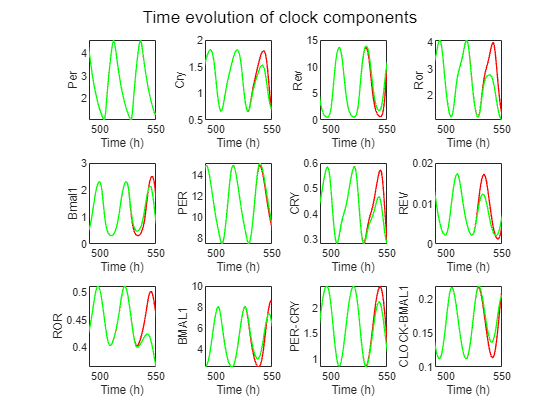

%% dark regions
ymin = 0; ymax = 100;
v2 = [446 ymin; 452 ymin; 452 ymax; 446 ymax;
    464 ymin; 476 ymin; 476 ymax; 464 ymax;
    488 ymin; 494 ymin; 494 ymax; 488 ymax];
f2 = [1 2 3 4;
    5 6 7 8;
    9 10 11 12];

clock_name = ["Per", "Cry", "Rev", "Ror", "Bmal1", "PER", "CRY", "REV", "ROR", "BMAL1", "PER-CRY", "CLOCK-BMAL1"];
figure;
for i = 1:12
    subplot(3, 4, i);
    plot(tspan, y1(:, i), 'r', 'LineWidth', 1); hold on;
%     plot(tspan, y2(:, i), 'k', 'LineWidth', 1); hold on;
    plot(tspan, y3(:, i), 'g', 'LineWidth', 1); hold on;
%     plot(tspan, y4(:, i), 'b', 'LineWidth', 1); hold on;
    xlim([490 550]);
%     xlim([446 494]);
%     yl = ylim;
%     patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
%     ylim(yl);
    xlabel('Time (h)');
    ylabel(clock_name(i));
end
sgtitle('Time evolution of clock components');
hold off;

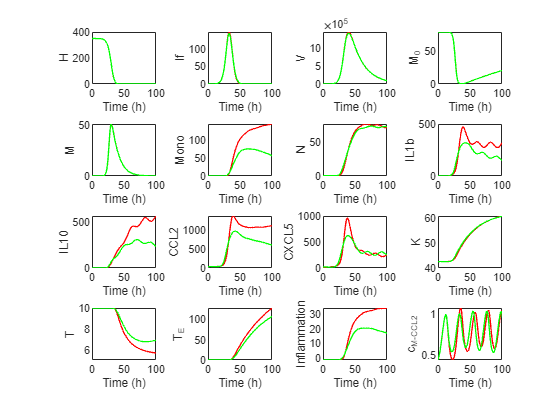


% figure;
% xSize = 30; X=xSize; ySize = 7;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
% set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
% hold on;
% subplot(1, 3, 1);
% plot(par_IAV(71) ./ (par_IAV(71) + y2(:, 8)) * par_IAV(20), 'k', 'LineWidth', 2); hold on;
% plot([100 200], [0.7 0.7], 'g', 'LineStyle', '--', 'LineWidth', 2); hold off;
% xlim([100 200]); ylim([0.6 1.3]); xlabel('Time (h)'); ylabel('c_{M-CCL2}'); title('Normal Clock');
% subplot(1, 3, 2);
% plot(par_IAV(71) ./ (par_IAV(71) + y3(:, 8)) * par_IAV(20), 'r', 'LineWidth', 2); hold on;
% plot([100 200], [0.7 0.7], 'g', 'LineStyle', '--', 'LineWidth', 2); hold off;
% xlim([100 200]); ylim([0.6 1.3]); xlabel('Time (h)'); ylabel('c_{M-CCL2}'); title('Clock Knock Out');
% subplot(1, 3, 3);
% plot(par_IAV(71) ./ (par_IAV(71) + y4(:, 8)) * par_IAV(20), 'b', 'LineWidth', 2); hold on;
% plot([100 200], [0.7 0.7], 'g', 'LineStyle', '--', 'LineWidth', 2); hold off;
% xlim([100 200]); ylim([0.6 1.3]); xlabel('Time (h)'); ylabel('c_{M-CCL2}'); title('Smaller Amplitude');

var_name = ["H", "If", "V", "M_0", "M", "Mono", "N", "IL1b", "IL10", "CCL2", "CXCL5", "K", "T", "T_E"];
figure;
for i = 13:26
    subplot(4, 4, i - 12);
%     plot(tspan, y(:, i), 'k', 'LineWidth', 1); hold on;
%     plot(tspan, y1(:, i), 'r', 'LineWidth', 1);
    plot(tspan - t_IAV_11, y1(:, i), 'r', 'LineWidth', 1); hold on;
%     plot(tspan - t_IAV_5, y2(:, i), 'k', 'LineWidth', 1); hold on;
    plot(tspan - t_IAV_23, y3(:, i), 'g', 'LineWidth', 1); hold on;
%     plot(tspan - t_IAV_23, y4(:, i), 'b', 'LineWidth', 1);
%     xlim([0 500]);
    xlim([0 100]);
%     xlim([446 494]);
%     yl = ylim;
%     patch('Faces', f2,'Vertices', v2, 'FaceColor', 'black', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
%     ylim(yl);
    xlabel('Time (h)');
    ylabel(var_name(i - 12)); hold off;
end
subplot(4, 4, 15);
plot(tspan - t_IAV_11, infla1, 'r', 'LineWidth', 1); hold on;
% plot(tspan - t_IAV_5, infla2, 'k', 'LineWidth', 1); hold on;
plot(tspan - t_IAV_23, infla3, 'g', 'LineWidth', 1); hold on;
% plot(tspan - t_IAV_23, infla4, 'b', 'LineWidth', 1);
% xlim([0 500]);
xlim([0 100]);
xlabel('Time (h)'); ylabel('Inflammation'); hold off;

subplot(4, 4, 16);
plot(tspan - t_IAV_11, par_IAV(20) .* par_IAV(71) ./ (par_IAV(71) + y1(:, 8)), 'r', 'LineWidth', 1); hold on;
plot(tspan - t_IAV_11, par_IAV(20) .* par_IAV(71) ./ (par_IAV(71) + y3(:, 8)), 'g', 'LineWidth', 1); 
xlim([0 100]);
xlabel('Time (h)'); ylabel('c_{M-CCL2}'); hold off;

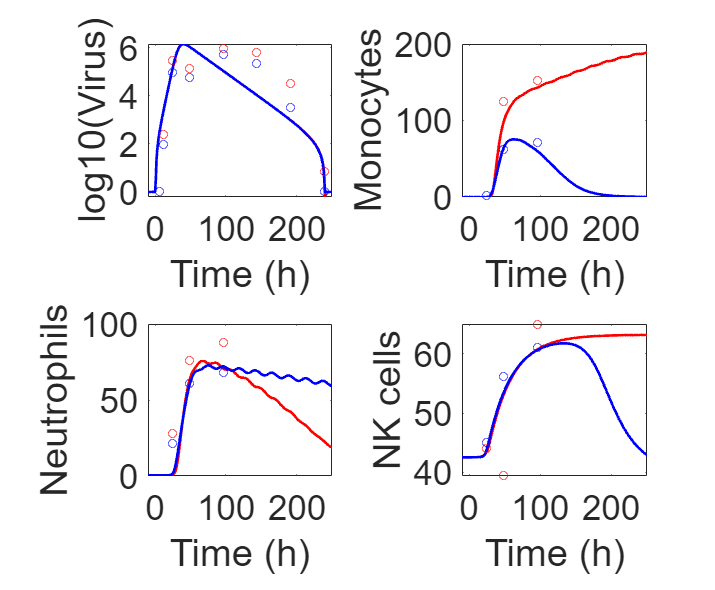

% legend('Only c_{M-IL10} oscillates', 'Only c_{M-CCL2} oscillates', 'Both oscillate', 'Location',[0.8 0.2 0 0]);
% legend('ZT11', 'ZT5', 'ZT23', 'ZT17', 'Location', [0.8 0.2 0 0]);
% legend('Normal Clock', 'Clock Knock Out', 'Smaller Amplitude', 'Location', [0.8 0.2 0 0]);
% sgtitle('Immune response of different infection time with intact clock');
% sgtitle('The circadian clock and immunity interact in both directions');
% sgtitle('c_{M-CCL2} is controlled by different clocks');
% sgtitle('Circadian control of c_{M-CCL2} and c_{M-IL10}');

figure;
xSize = 20; X=xSize; ySize = 15;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(2, 2, 1); hold on; set(gca,'Fontsize',26); box on;
plot(tspan - t_IAV_11, Safe_log10(y1(:, 15) - 100), 'r', 'LineWidth', 2); hold on;
plot(tspan - t_IAV_23, Safe_log10(y3(:, 15) - 100), 'b', 'LineWidth', 2);
scatter(data_v(1, :), data_v(3, :), 'r');
scatter(data_v(1, :), data_v(2, :), 'b');
xlim([-10 250]);
xlabel('Time (h)'); ylabel('log10(Virus)');
hold off;

subplot(2, 2, 2); hold on; set(gca,'Fontsize',26); box on;
plot(tspan - t_IAV_11, y1(:, 18), 'r', 'LineWidth', 2); hold on;
plot(tspan - t_IAV_23, y3(:, 18), 'b', 'LineWidth', 2);
scatter(data_mono(1, 1:3), data_mono(3, 1:3), 'red');
scatter(data_mono(1, 1:3), data_mono(2, 1:3), 'blue');
xlim([-10 250]);
xlabel('Time (h)'); ylabel('Monocytes');
hold off;

subplot(2, 2, 3); hold on; set(gca,'Fontsize',26); box on;
plot(tspan - t_IAV_11, y1(:, 19), 'r', 'LineWidth', 2); hold on;
plot(tspan - t_IAV_23, y3(:, 19), 'b', 'LineWidth', 2);
scatter(data_neu(1, 1:3), data_neu(3, 1:3), 'red');
scatter(data_neu(1, 1:3), data_neu(2, 1:3), 'blue');
xlim([-10 250]);
xlabel('Time (h)'); ylabel('Neutrophils');
hold off;

subplot(2, 2, 4); hold on; set(gca,'Fontsize',26); box on;
plot(tspan - t_IAV_11, y1(:, 24), 'r', 'LineWidth', 2); hold on;
plot(tspan - t_IAV_23, y3(:, 24), 'b', 'LineWidth', 2);
scatter(data_nk(1, 1:3), data_nk(3, 1:3), 'red');
scatter(data_nk(1, 1:3), data_nk(2, 1:3), 'blue');
xlim([-10 250]);
xlabel('Time (h)'); ylabel('NK cells');
hold off;

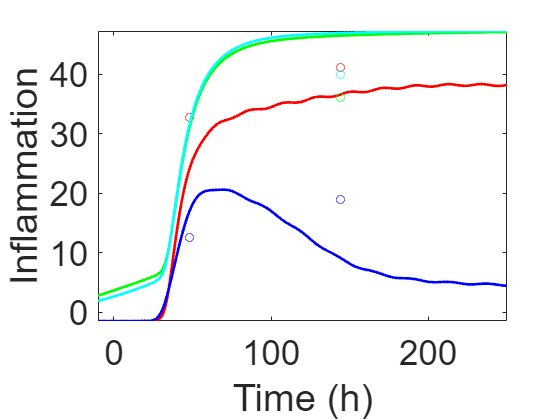


% subplot(2, 3, 5);
% plot(tspan - t_IAV_11, y1(:, 26), 'r', 'LineWidth', 1); hold on;
% plot(tspan - t_IAV_23, y3(:, 26), 'b', 'LineWidth', 1);
% scatter(data_te(1, :), data_te(3, :), 'red');
% scatter(data_te(1, :), data_te(2, :), 'blue');
% xlim([-10 250]);
% xlabel('Time (h)'); ylabel('T_E');
% hold off;

% subplot(1, 3, 3);
% plot(tspan - t_IAV_11, y1(:, 22), 'r', 'LineWidth', 1); hold on;
% plot(tspan - t_IAV_23, y3(:, 22), 'b', 'LineWidth', 1);
% scatter(data_ccl2(1, :), data_ccl2(3, :), 'red');
% scatter(data_ccl2(1, :), data_ccl2(2, :), 'blue');
% xlim([-10 250]);
% xlabel('Time (h)'); ylabel('CCL2');
% hold off;

% Inflammation and survival curve
figure; hold on; set(gca,'Fontsize',26); box on;
plot(tspan - t_IAV_11, infla1, 'r', 'LineWidth', 2); hold on;
plot(tspan - t_IAV_23, infla3, 'b', 'LineWidth', 2); 
scatter(data_inf_score(1, 1:2), data_inf_score(3, 1:2), 'red');
scatter(data_inf_score(1, 1:2), data_inf_score(2, 1:2), 'blue');

plot(tspan - t_IAV_11, infla1_ko, 'g', 'LineWidth', 2);
plot(tspan - t_IAV_23, infla3_ko, 'c', 'LineWidth', 2);
scatter(144, 36, 'green');
scatter(144, 40, 'cyan');

xlim([-10 250]);
xlabel('Time (h)'); ylabel('Inflammation');
hold off;

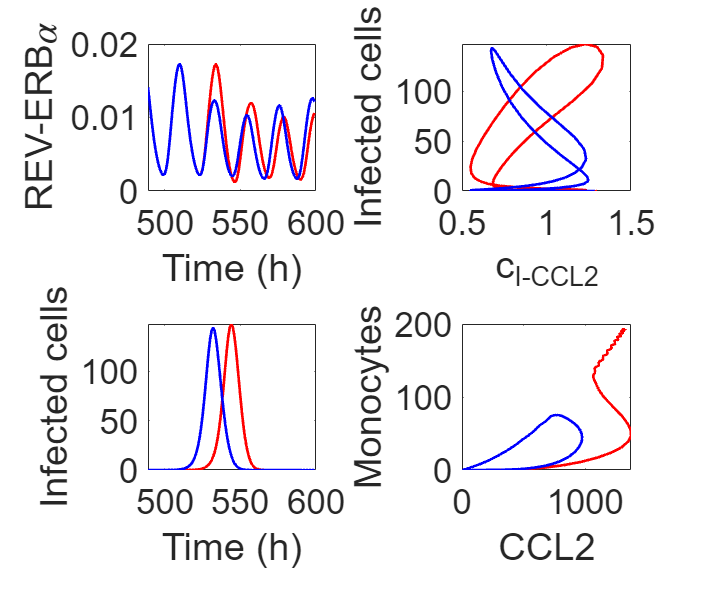



figure;
xSize = 20; X=xSize; ySize = 15;xLeft = (xSize-xSize)/2; Y=ySize; yTop = (ySize-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);set(gcf,'Position',[X Y xSize*50 ySize*55]);
hold on;
subplot(2, 2, 1); hold on; set(gca,'Fontsize',26); box on;
plot(tspan(490:600), y1(490:600, 8), 'r', 'LineWidth', 2); hold on;
plot(tspan(490:600), y3(490:600, 8), 'b', 'LineWidth', 2); 
xlabel('Time (h)'); ylabel('REV-ERB{\alpha}');
hold off;
subplot(2, 2, 2); hold on; set(gca,'Fontsize',26); box on;
plot(par_IAV(21) .* par_IAV(71) ./ (par_IAV(71) + y1(490:600, 8)), y1(490:600, 14), 'r', 'LineWidth', 2); hold on;
plot(par_IAV(21) .* par_IAV(71) ./ (par_IAV(71) + y3(490:600, 8)), y3(490:600, 14), 'b', 'LineWidth', 2);
xlabel('c_{I-CCL2}'); ylabel('Infected cells');
hold off;
subplot(2, 2, 3); hold on; set(gca,'Fontsize',26); box on;
plot(tspan(490:600), y1(490:600, 14), 'r', 'LineWidth', 2); hold on;
plot(tspan(490:600), y3(490:600, 14), 'b', 'LineWidth', 2);
xlabel('Time (h)'); ylabel('Infected cells');
hold off;
subplot(2, 2, 4); hold on; set(gca,'Fontsize',26); box on;
plot(y1(490:800, 22), y1(490:800, 18), 'r', 'LineWidth', 2); hold on;
plot(y3(490:800, 22), y3(490:800, 18), 'b', 'LineWidth', 2);
xlabel('CCL2'); ylabel('Monocytes');
hold off;